# High Voltage Battery - Main Script

## Harness Model

A harness model is used to test the main component, which is **High Voltage Battery** referenced subsystem.

mdl = "BatteryHV_harness_model";
load_system(mdl)

% Load model parameters.
BatteryHV_harness_setup

refsub_type = "Basic";
% refsub_type = "Driveline";
% refsub_type = "Electrical";

refsub = "BatteryHV_refsub_" + refsub_type

refsub = "BatteryHV_refsub_Basic"

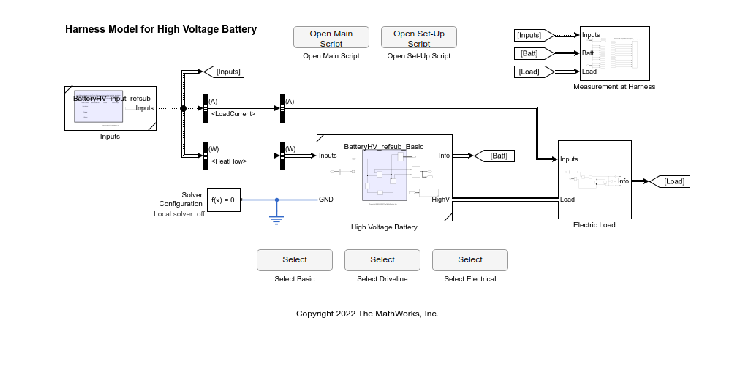


% Set referenced subsystem.
set_param(mdl + "/High Voltage Battery", ...
  "ReferencedSubsystem", "BatteryHV_refsub_"+refsub_type)

imgFolder = fullfile( currentProject().RootFolder, ...
              "Components", "BatteryHighVoltage", "images" );

imgFilePath = fullfile(imgFolder, "image_" + mdl + ".png");
assert(isfile(imgFilePath))
imshow(imgFilePath)

## High Voltage Battery Component Subsystem

This subsystem is the main component under test. This is also used in a system-level model.

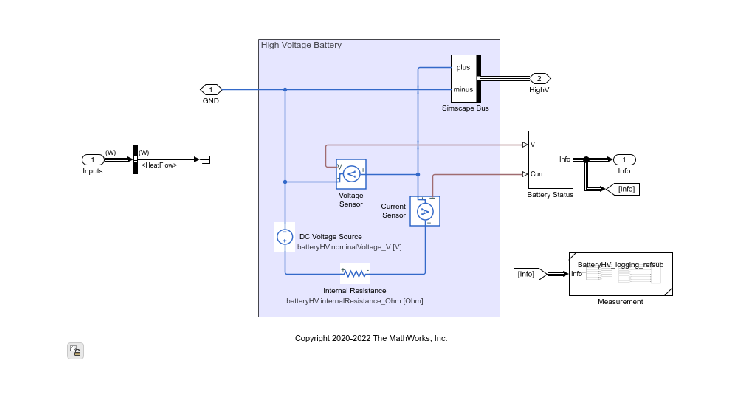

imgFilePath = fullfile(imgFolder, "image_" + refsub + ".png");
assert(isfile(imgFilePath))
imshow(imgFilePath)

## Simulation

### Basic Check

This simple simulation checks that the model runs ok.

% External input signals
sigBuilder = BatteryHV_InputSignalBuilder;

inpData = Constant(sigBuilder);

batteryHV_InputSignals = inpData.Signals;
batteryHV_InputBus = inpData.Bus;
initial.hvBattery_Charge_Ahr = inpData.Options.InitialCharge_Ahr;
ambient.temp_K =  273.15 + inpData.Options.InitialTemperature_degC;
initial.hvBattery_Temperature_K = ambient.temp_K;

t_end = inpData.Options.StopTime_s;

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

% Run simulation
simOut = sim(simIn);

Temperature plot is empty in the basic simulation because it is not modeled.

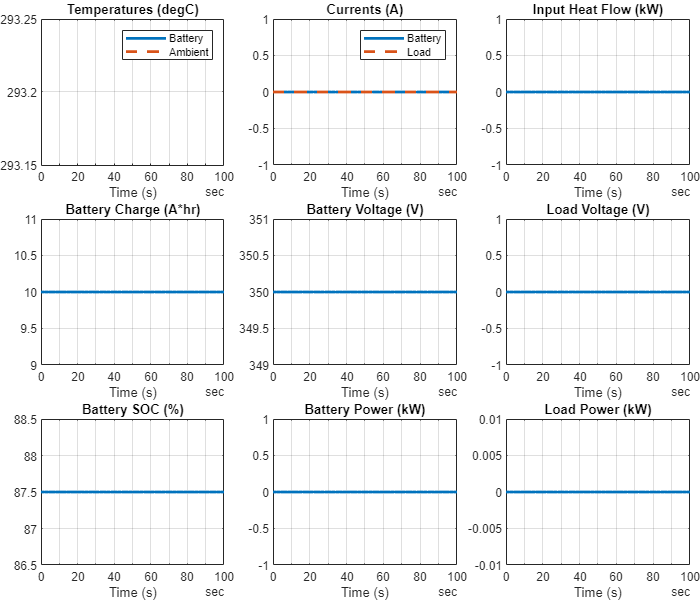

logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals)

finishRunningScript = true;
switch finishRunningScript
case true
  % The execution of this script stops here.
  return
end

### Discharge

 
edit("BatteryHV_testcase_Discharge.mlx")

### Charge

 
edit("BatteryHV_testcase_Charge.mlx")

### 3 Step Load Current

 
edit("BatteryHV_testcase_LoadCurrentStep3.mlx")

*Copyright 2020-2022 The Mathworks, Inc.*